m = 2000 %kg masse vom KFZ

m = 2000

J = 4000 %kgm^2 massenträgheitsmoment

J = 4000

l_v = 1.43 %m  länge vorne 

l_v = 1.4300

l_h = 1.4 %m länge hinten

l_h = 1.4000


%Schräglaufkoeffizienten
c_v = 70000 % N/rad 

c_v = 70000

c_h = 140000 % N/rad 

c_h = 140000


delta = 5 *  pi /180 % rad

delta = 0.0873

v = 18 %m/s

v = 18

alpha_v = @(beta, psi_dot) delta - (l_v * psi_dot / (v* cos(beta))) + tan(beta);
alpha_h = @(beta, psi_dot)  (l_h * psi_dot / (v* cos(beta))) - tan(beta);

%f = @(t,Y) [Y(2); -3*Y(2) - 2*Y(1)];

%Zustandsvektor vom System
%Y = [beta, psi_dot]

t = [0 25]; % Zeitvektor in s

f_1  = @( beta, psi_dot) (-1)*psi_dot + (1/(m*v)*(c_v * alpha_v(beta, psi_dot)* (cos(delta)/cos(beta)) + c_h * alpha_h(beta, psi_dot)* (1/cos(beta))));

f_2 = @(beta, psi_dot) (1/J)*(l_v * c_v * alpha_v(beta, psi_dot) * cos(delta) - l_h * c_h * alpha_h(beta, psi_dot));

f = @(t, Y) [f_1(Y(1), Y(2)); f_2(Y(1),Y(2))];

opts = odeset( ...
    'RelTol', 1e-6, ...
    'AbsTol', [1e-9 1e-9], ...   % AbsTol pro Zustand (beta, psi_dot)
    'MaxStep', 0.01, ...         % maximale Schrittweite
    'InitialStep', 1e-3, ...     % Anfangsschrittweite
    'Stats','on' );

[t_nonlin_ss, x_nonlin_ss] = ode113(f, t, [0; 0], opts);

2517 successful steps
4 failed attempts
5039 function evaluations


beta_nonlin_ss = x_nonlin_ss(:,1);
psi_dot_nonlin_ss = x_nonlin_ss(:,2)

psi_dot_nonlin_ss =          0
    0.0000
    0.0001
    0.0001
    0.0002
    0.0004
    0.0007
    0.0014
    0.0021
    0.0027
    0.0041
    0.0068
    0.0121
    0.0175
    0.0228


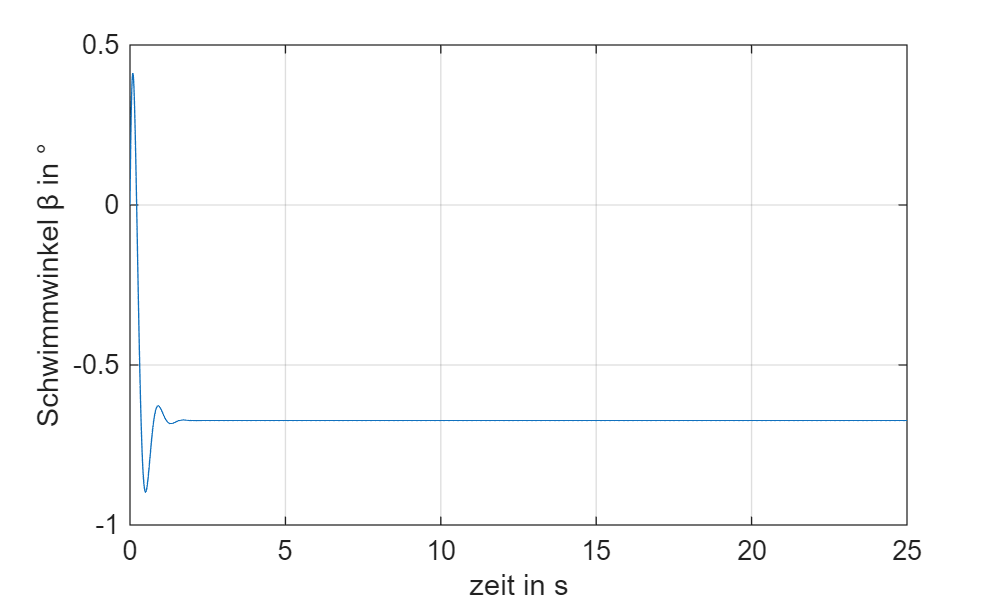


figure; plot(t_nonlin_ss, beta_nonlin_ss * 180/pi, '-')
grid on, xlabel('zeit in s'), ylabel('Schwimmwinkel β in °')

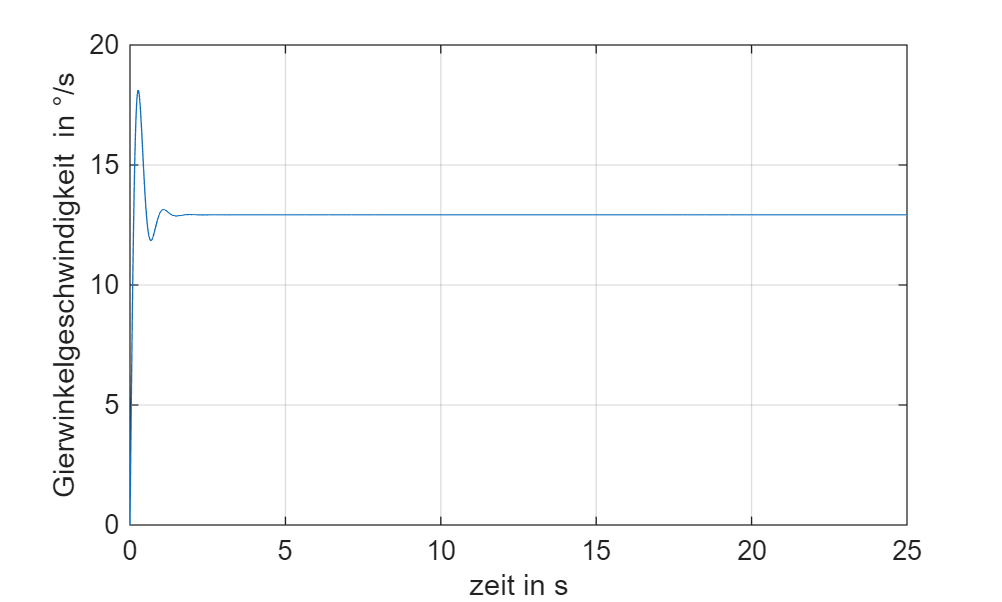



figure; plot(t_nonlin_ss, psi_dot_nonlin_ss * 180 /pi, '-')
grid on, xlabel('zeit in s'), ylabel('Gierwinkelgeschwindigkeit  in °/s')


opts = odeset('Stats','on', 'RelTol',1e-6, 'AbsTol',[1e-9 1e-9]);
[t45,x45] = ode113(f, [0 25], [0;0], opts);

239 successful steps
11 failed attempts
490 function evaluations



dt = diff(t_nonlin_ss);
[min(dt) max(dt)]

ans =     0.0000    0.0100



%Prüfung der Konvergenz
optsA = odeset('RelTol',1e-6,'AbsTol',[1e-9 1e-9],'Stats','on');
optsB = odeset('RelTol',1e-8,'AbsTol',[1e-11 1e-11],'Stats','on');

solA = ode45(f,[0 25],[0;0],optsA);

119 successful steps
16 failed attempts
811 function evaluations


solB = ode45(f,[0 25],[0;0],optsB);

212 successful steps
10 failed attempts
1333 function evaluations



tq = 0:0.01:25;
xA = deval(solA,tq).';
xB = deval(solB,tq).';

err = max(vecnorm(xB-xA,2,2));
fprintf('max error between tolerances: %.3e\n', err);

max error between tolerances: 2.176e-07




fprintf('finite check A: %d\n', all(isfinite(xA),'all'));

finite check A: 1


fprintf('finite check B: %d\n', all(isfinite(xB),'all'));

finite check B: 1


fprintf('finite check Solution: %d\n', all(isfinite(x_nonlin_ss),'all'));

finite check Solution: 1




mdl = "linear_Einspurmodel";
load_system(mdl)

t = (0:0.01:10)';                 
u = 5 * ones(size(t));   % Sprung

u_ext = [t u];                    % [time  input]
v = 18

v = 18

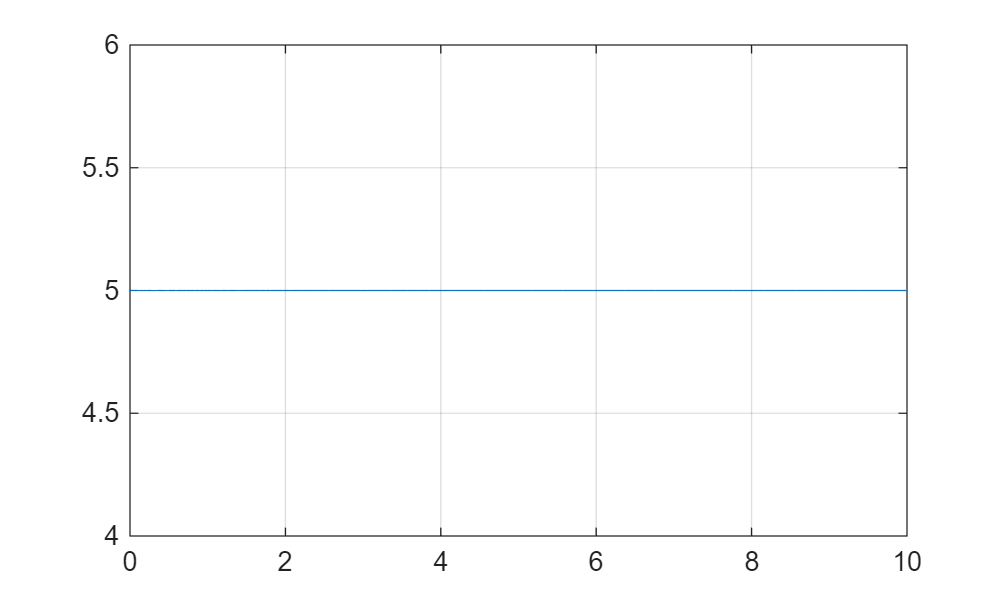


set_param(mdl,'LoadExternalInput','on');
set_param(mdl,'ExternalInput','u_ext');
simOut = sim(mdl,'StopTime','10');

beta_ts   = simOut.logsout.getElement('beta').Values;
delta_ts = simOut.logsout.getElement('delta_in').Values;
plot(delta_ts.Time, delta_ts.Data); grid on

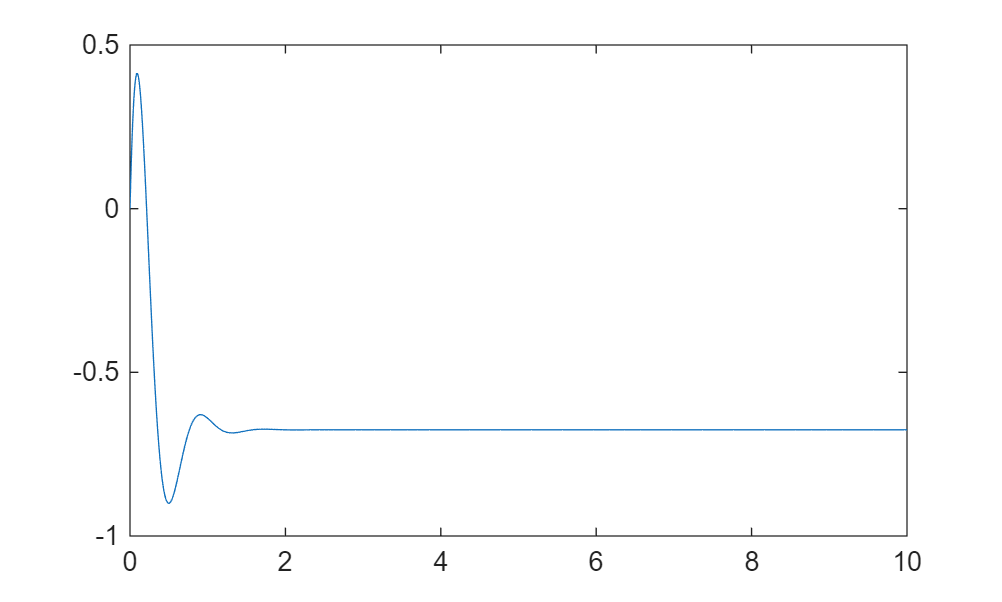

plot(beta_ts.Time, beta_ts.Data)

function J = cost_beta(v)

    mdl = "linear_Einspurmodel";

    % Geschwindigkeit setzen
    assignin('base','v',v);

    % Lenkwinkel-Sprung (5°)
    t = (0:0.01:10)';
    u = deg2rad(5) * ones(size(t));
    u_ext = [t u];
    assignin('base','u_ext',u_ext);

    set_param(mdl,'LoadExternalInput','on');
    set_param(mdl,'ExternalInput','u_ext');

    simOut = sim(mdl,'StopTime','10');

    beta_ts = simOut.logsout.getElement('beta').Values;
    beta = beta_ts.Data;

    % stationärer Wert (robust)
    beta_ss = mean(beta(end-50:end));

    % Kostenfunktion
    J = beta_ss^2;

end

mdl = "linear_Einspurmodel";
load_system(mdl)

v_min = 1;
v_max = 50;

[v_opt, J_opt] = fminbnd(@cost_beta, v_min, v_max);

disp("Optimale Geschwindigkeit:")

Optimale Geschwindigkeit:


disp(v_opt)

   13.9264




disp("Minimaler Wert:")

Minimaler Wert:


disp(J_opt)

   1.0511e-18



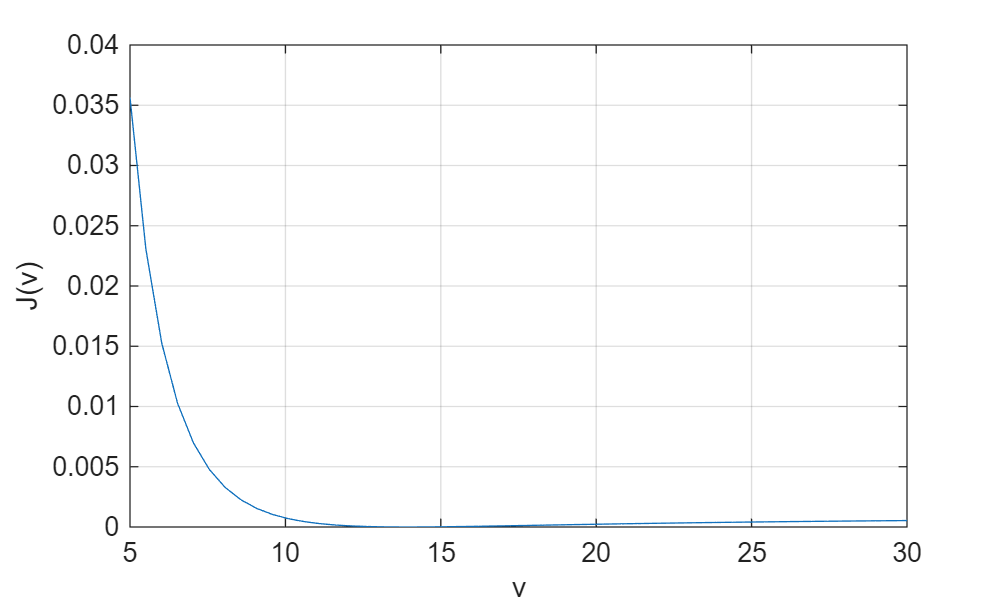

v_test = linspace(5,30,50);
J = zeros(size(v_test));

for i = 1:length(v_test)
    J(i) = cost_beta(v_test(i));
end

plot(v_test, J)
grid on
xlabel('v')
ylabel('J(v)')